format long 
syms y(x)

% find the exact solutions function first 
Dy = diff(y);

% plug in the ode equation
ode = diff(y,x,2) + 0.25*diff(y,x,1) == 8;

% input the ode boundary conditions
cond1 = y(0) == 0;
cond2 = y(10) == 0;

% solve for the pde
conds = [cond1 cond2];
ySol(x) = dsolve(ode,conds);
ySol = simplify(ySol)

$$ySol(x) = 32\,x+\frac{320\,{\mathrm{e}}^{\frac{5}{2}-\frac{x}{4}}}{{\mathrm{e}}^{5/2}-1}-\frac{64\,\left(3\,{\mathrm{e}}^{5/2}+2\right)}{{\mathrm{e}}^{5/2}-1}-128$$

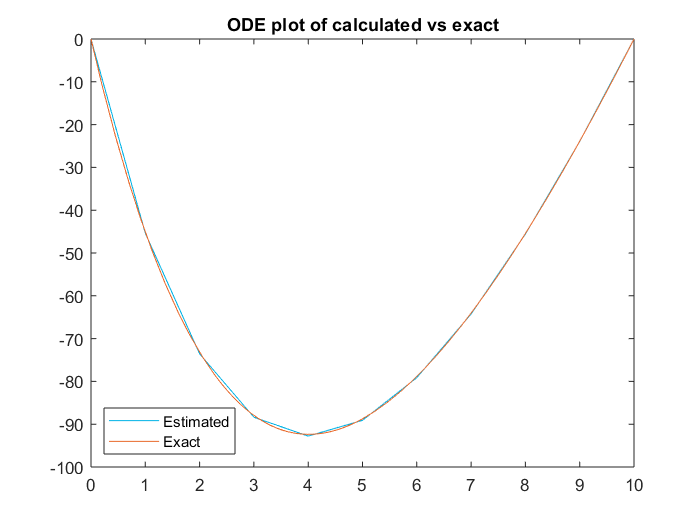


% set the delta x to 1 and find the points in the domain
del_X = 1;

% set last number of pts
N = 10;
% set the boundary conditions 
x = 0:del_X:N;

% convergence conditions
accuracy = 10^-4;

% create the unknown matrices for y
y = zeros(N+1,1);
y(1) = 0;
y(N+1) = 0;

% allocate memory for temp value
temp = zeros(11,1);

% stopping condition based on chose accuracy
stop = 1;

while stop>0
    % calculate the new values of the unknowns 
    for i=1:N-1
        temp(i+1) = (y(i+2)*(1+del_X/8)+y(i)*(1-del_X/8)-8*del_X^2)/2;
    end
    temp(1) = y(1);
    temp(N+1) = y(N+1);
    
    stop = 0;
    % stop the function when it hits the threshold of accuracy
    for i=1:N+1
        if(abs(y(i)-temp(i)) > accuracy)
            stop = 1;
            break;
        end
    end
    y = temp;
end

% plot functions
plot(x,y,'Color',[0,0.7,0.9])
hold on
fplot(ySol, [0,10],'Color',[0.9100,0.4100,0.1700])
legend({'Estimated','Exact'},'Location','southwest')
title('ODE plot of calculated vs exact')
hold off